# Caso de Estudo - Sistema de Controle de Nível e Concentração

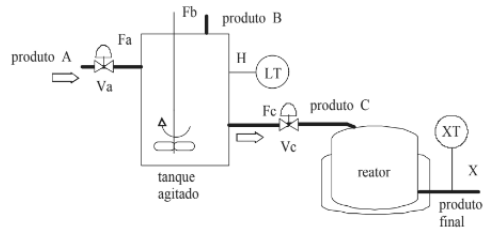

Definido s como transformada de laplace:

s = tf('s');

## **Dados e Modelos:**

**Concentração X**

Gx = 2/(8*s + 1);

**Perturbação Q**

Gq = 1/(8*s + 1);

**Nivel H**

Gh = 5/(4*s + 1);

**Perturbação Vc**

Gvc = 1/(3*s + 1);

## Resolução:

### Diagrama de blocos de Malha aberta:

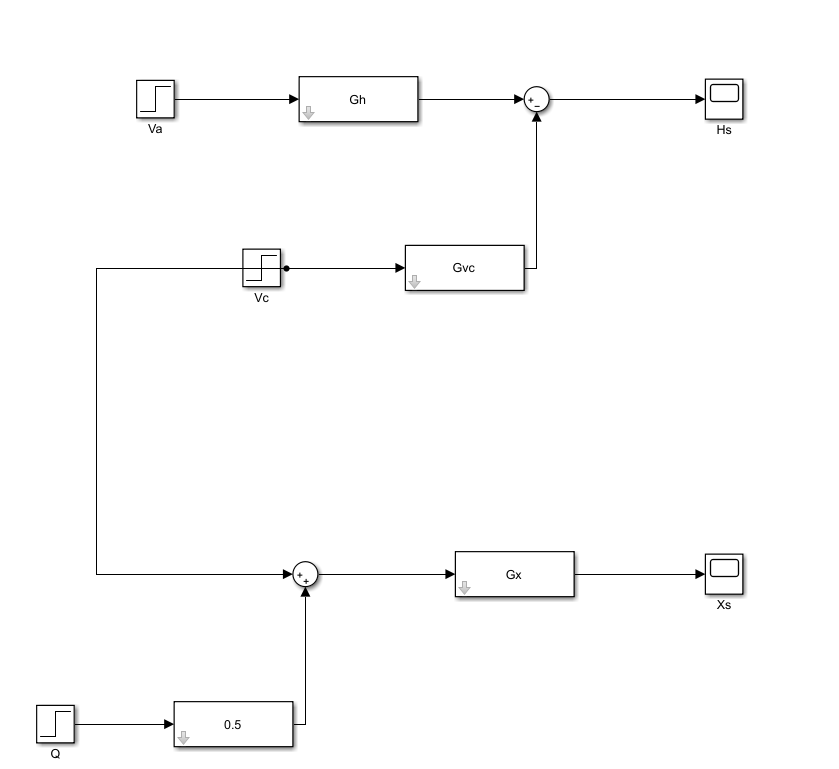

## Proposta de controle:

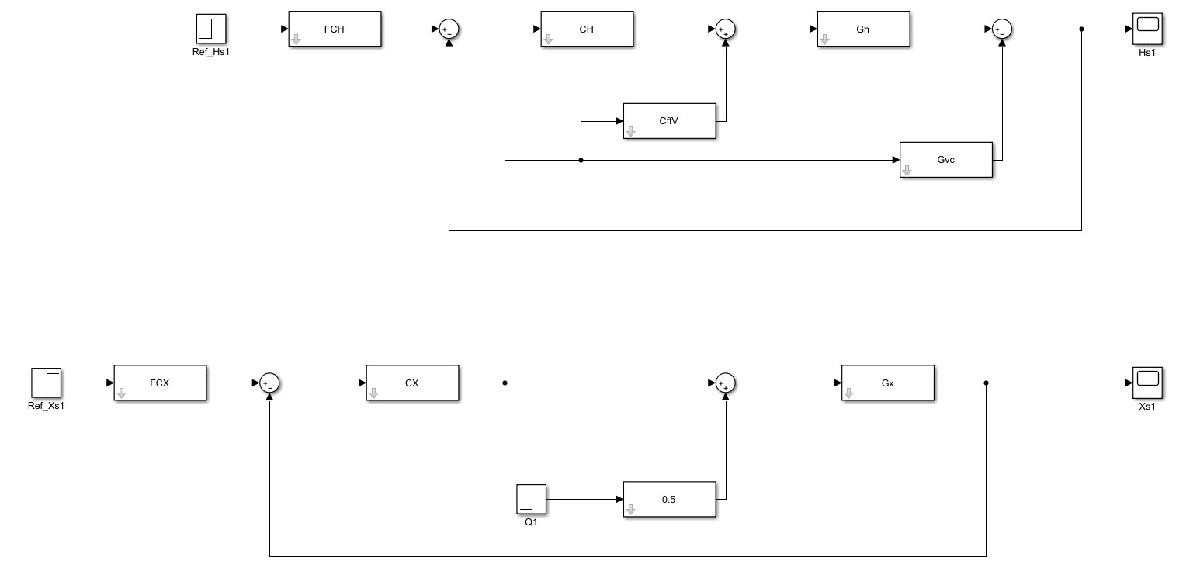

imagem está saindo bugada aqui

### Objetivo da Estrutura de Controle H(s)

Foi utilizado uma estrutura de controle para H(s), que é o sistema de nivel do tanque em paralelo a X(s), pois elas são duas saídas, por isso foram propostos duas malhas diferentes. Para a rejeição da perturbação Vc foi utilizado um Controlador FeedForward, visto que Vc é uma variavel controlada, portanto mensurável.

#### Requisitos:

Sobressinal 0.10 

t5 <= 3 seg para referencia e rejeitar Perturbação Vc

GDC = 1 para referencia 

GDC = 0 para perturbação

### Projeto de controle de CHs:

MP = 0.10, t5 = 3

Ti = 0.611562479475106;
Kc = 1.4;

Controlador 

CH = (Kc*(Ti*s+1))/(Ti*s)

CH =
 
  0.8562 s + 1.4
  --------------
     0.6116 s
 
Continuous-time transfer function.



Calculando a Tr:

Tr = (CH * Gh)/(1+ CH * Gh);
Tr = (minreal(Tr,0.0001))

Tr =
 
   1.75 s + 2.862
  -----------------
  s^2 + 2 s + 2.862
 
Continuous-time transfer function.



#### Analise CHs

 Resposta ao degrau de Tr

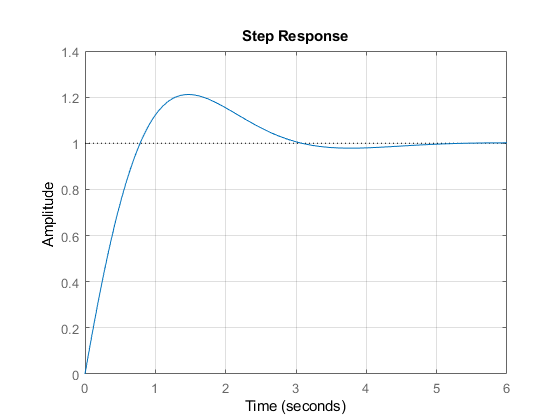

figure;
step(Tr)
grid on

Diagrama Polo e Zero - DPZ

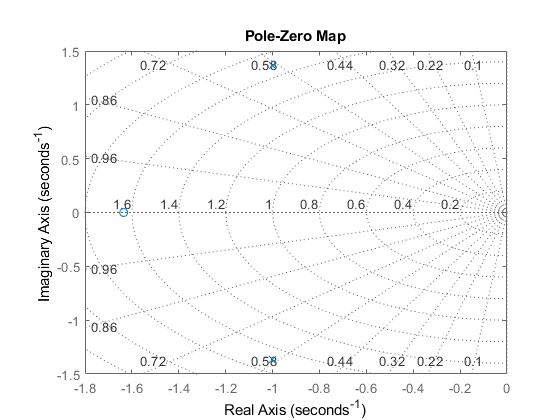

figure;
pzmap(Tr) 
grid on

Como podemos observar aparece um zero indesejado, projetamos um filtro para retirar esse zero:

FCH = 1/(Ti*s + 1);
TrfH = FCH * Tr;
TrfH = (minreal(TrfH,0.00001))

TrfH =
 
        2.862
  -----------------
  s^2 + 2 s + 2.862
 
Continuous-time transfer function.



atende a T desejada e calculada a mão.

Resposta ao degrau de Tr

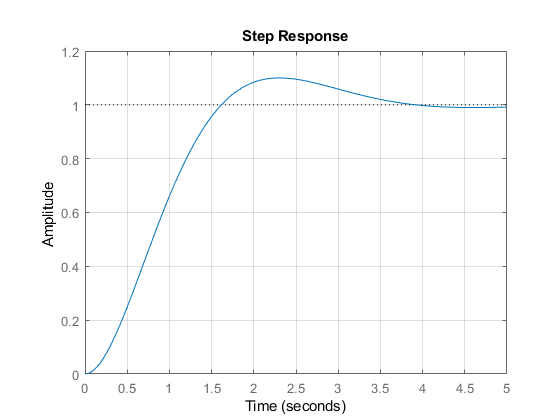

figure;
step(TrfH) 
grid on

info = stepinfo(TrfH,'SettlingTimeThreshold',0.05);

Tempo de 5% para Referencia:

T5MFH = info.SettlingTime

T5MFH = 3.1020

o tempo mostrado no matlab é de 3.1020, onde era para ser 3 segundos, porém acredita-se ser um erro numerico pois, nos calculos a mão atendeu corretamente. 

Sobressinal, sem sobressinal

MPH = info.Overshoot

MPH = 10.0000

sobressinal em 10% atendendo como o que foi pedido

Ganho DC = 1, garante seguinte de referência

GDCH = dcgain(Tr)

GDCH = 1.0000

atendeu corretamente

Controlador FF para a perturbação Vc(s):

CffV = (1/5)*((4*s + 1)/((3*s +1)))

CffV =
 
  0.8 s + 0.2
  -----------
    3 s + 1
 
Continuous-time transfer function.



## Objetivo da Estrutura de Controle X(s)

Foi utilizado uma estrutura de controle para X(s), que é quem controla a concentração na saída no reator, em paralelo a H(s), que é o sistema de nivel do tanque, pois elas são duas saídas, por isso foram propostos duas malhas diferentes.

Objetivo contole CXs

Sem Sobressinal 

t5 <= 5 seg para referencia e rejeitar Perturbação Q

GDC = 1 para referencia 

GDC = 0 para perturbação

#### Projeto para CX

MP = 0, t5 = 5

Ti = 1.9476996527777777777777777777778;
Kc = 7.18;

Controlador 

CX = (Kc*(Ti*s+1))/(Ti*s)

CX =
 
  13.98 s + 7.18
  --------------
     1.948 s
 
Continuous-time transfer function.



Calculando a Tr:

Tr = (CX * Gx)/(1 + CX * Gx);
Tr = zpk(minreal(Tr,0.0001))

Tr =
 
  1.795 (s+0.5134)
  ----------------
     (s+0.96)^2
 
Continuous-time zero/pole/gain model.



###  Analise CX

 Resposta ao degrau de Tr

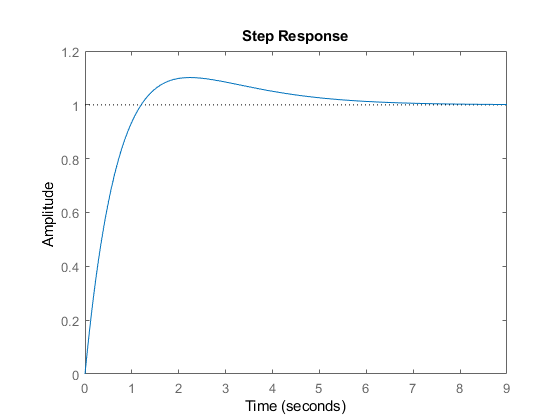

figure;
grid on
step(Tr) 

Diagrama Polo e Zero - DPZ

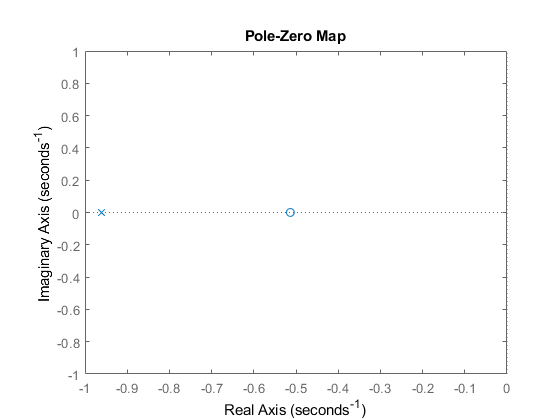

figure;
grid on
pzmap(Tr)

 Como podemos observar aparece um zero indesejado, projetamos um filtro para retirar esse zero:

FCX = 1/(Ti*s+1);
TrfCX = FCX * Tr;
TrfCX = minreal(TrfCX,0.00001)

TrfCX =
 
    0.9216
  ----------
  (s+0.96)^2
 
Continuous-time zero/pole/gain model.



atende a T desejada

Verificar se atende os requisitos:

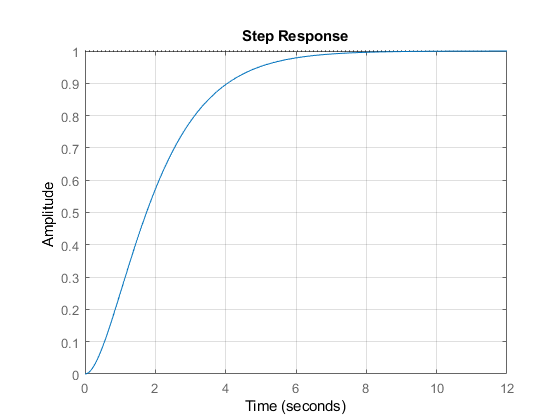

figure;
step(TrfCX)
grid on

info = stepinfo(TrfCX,"SettlingTimeThreshold",0.05)

info = struct with fields:
        RiseTime: 3.4983
    SettlingTime: 4.9415
     SettlingMin: 0.9019
     SettlingMax: 0.9999
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9999
        PeakTime: 12.4244


Tempo de acomodação t5:

T5MFX = info.SettlingTime

T5MFX = 4.9415

o tempo mostrado no matlab ficou em 4.9415 segundos, portanto menor que 5segundos, atendendo ao requisito.

Sobressinal:

MPX = info.Overshoot

MPX = 0

como é possivel observar ficou Sem sobressinal atendendo ao requisito.

Ganho DC:

GDCX= dcgain(TrfCX)

GDCX = 1

ganho dc igual a 1 atendendo ao requisito

Analisar Tp:

Tp = Gq/(CX*Gx+1);
Tp = zpk(minreal(Tp,0.0001))

Tp =
 
   0.125 s
  ----------
  (s+0.96)^2
 
Continuous-time zero/pole/gain model.



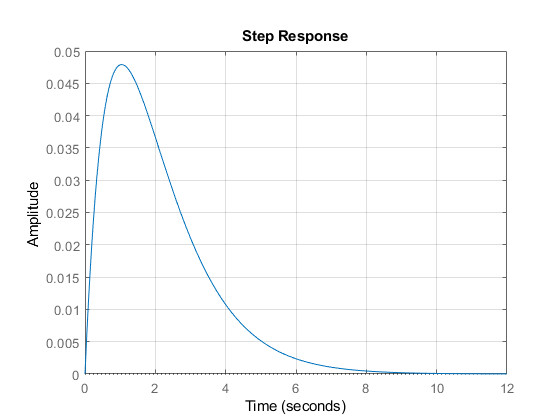

figure;
step(Tp)
grid on

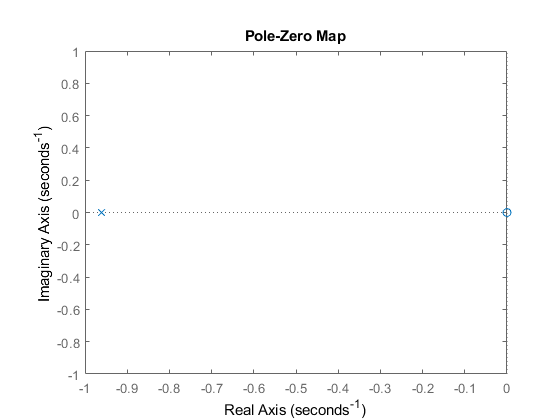


figure;
pzmap(Tp)

Ganho DC:

GDCp= dcgain(Tp)

GDCp = 0

ganho dc da perturbação igual a zero atendendo os requisitos

## Simulação do Sitemas Completo:

out = sim('Nivel_Concentracao.slx');

 Executa o arquivo do simulink

### Cenário simulado:

Mudança de reférência do tipo degrau em 5seg para H(s)

Mudança de reférência do tipo degrau em 5seg para H(s)

20seg Perturbação em Q com amplitude 1

#### Erros dos controladores

figure;
subplot(2,1,1)
plot(out.Erro.signals.values(:,1), 'LineWidth', 2)
xlabel("Time(s)")
ylabel("Erro de CH(s)")
grid on
xlim([0 25])
ylim([0 1.2])
yticks([0:0.25:1.2])

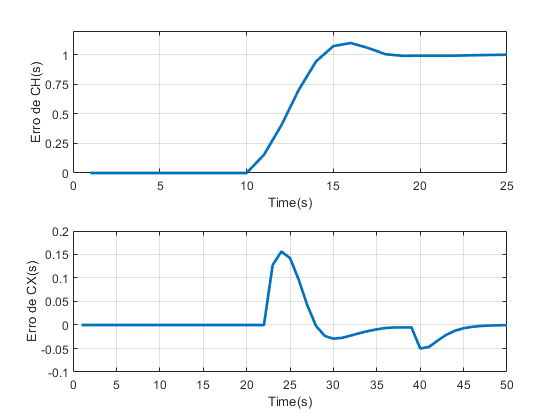

subplot(2,1,2)
plot(out.Erro.signals.values(:,2),'LineWidth',2)
xlabel("Time(s)")
ylabel("Erro de CX(s)")
grid on
xlim([0 50])
ylim([-0.1 0.2])
yticks([-0.1:0.05:0.25])

Sinal do erro dos controladores CH(s), e CX(s), observa-se que os dois controladores conseguem sempre levar o erro para zero após cada perturbação ou mudanção de referência garantindo assim o erro nulo em regime permanente

#### filtro CH:

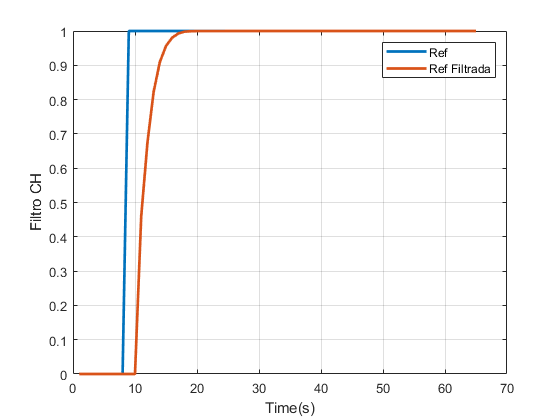

figure;
plot(out.FCH.signals.values(:,1),'LineWidth',2)
hold on
plot(out.FCH.signals.values(:,2),'LineWidth',2)
xlabel('Time(s)')
ylabel('Filtro CH')
legend('Ref','Ref Filtrada')
grid on

Podemos Observar a ação do filtro de referência do sistema, ele somente atua quando ocorre uma mudança de referência no sistema, e observa-se tambem que a referencia filtra suaviza a mudança de referência do sistema. e em regime permanente a referência filtra converge para o valor real, pois o filtro possui ganho DC = 1.

#### filtro CX:

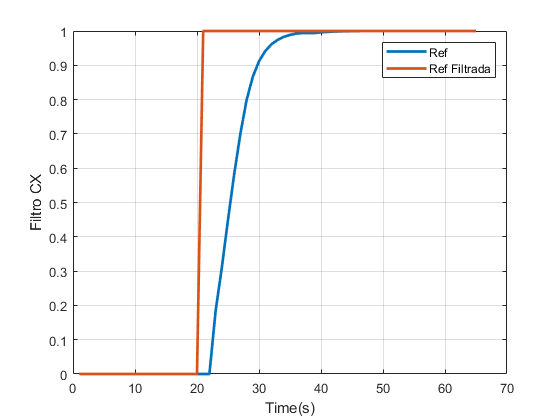

figure;
plot(out.FCX.signals.values(:,1),'LineWidth',2)
hold on
plot(out.FCX.signals.values(:,2),'LineWidth',2)
xlabel('Time(s)')
ylabel('Filtro CX')
legend('Ref','Ref Filtrada')
grid on

Podemos observar também a ação do filtro de referência CX do sistema, ele somente atua quando ocorre uma mudança de referência no sistema, e  observa-se tambem que a referencia filtra suaviza a mudança de referência do sistema. e em regime permanente a referência filtra converge para o valor real, pois o filtro possui ganho DC = 1.

####  Controle de H(s):

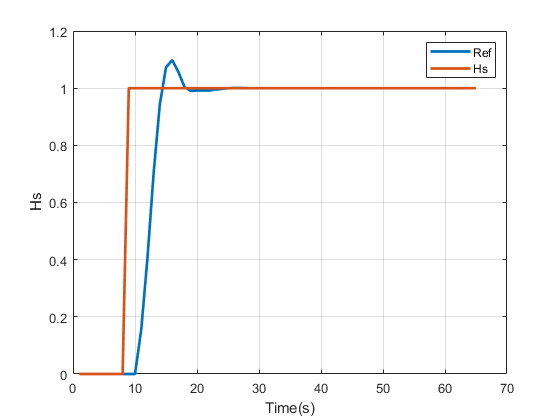

figure;
plot(out.Hs.signals.values(:,1),'LineWidth',2)
hold on
plot(out.Hs.signals.values(:,2),'LineWidth',2)
xlabel("Time(s)")
ylabel("Hs")
legend('Ref','Hs')
grid on

Observa-se que o controlador CH consegue seguir as referências dadas com o sobressinal dentro do requisito, no instante 10 quando a perturbação V atua no sistema observa-se que o cff ajuda o e ele pode ignora-lá;

####  Controle de X(s):

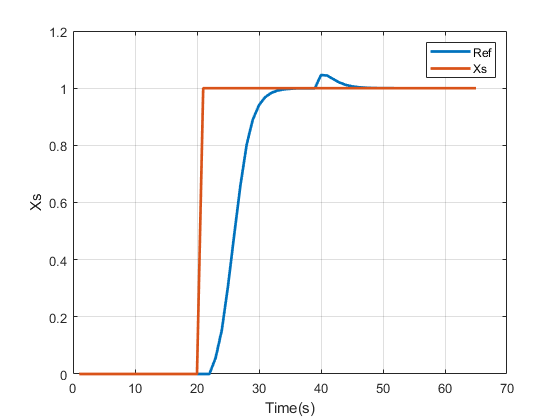

figure;
plot(out.Xs.signals.values(:,1),'LineWidth',2)
hold on
plot(out.Xs.signals.values(:,2),'LineWidth',2)
xlabel("Time(s)")
ylabel("Xs")
legend('Ref','Xs')
grid on

 Observa-se que o controlador CX consegue seguir as referências dadas com zero de sobressinal, mas no instante  20 quando a perturbação Q atua no sistema ela causa um sobressinal indesejado.